# **Impedance Model**

## Second order model representation

If we consider that a simple mass $M$, damper $B$, spring $K$, system is to be able to model the impedance behaviour of the human arm along an axis $\overrightarrow{x}$, while interacting with an environment then, we can write:

$\left({Ms}^2 +Bs+K\right)X_e \left(p\right)=F_e \left(p\right)$,

with$X$ the endpoint position of the arm, and $F$ the force of the arm on the environment, both along $\overrightarrow{x}$.

clear all
syms Ms Bs Ks;

The state representation of the system is:

$\dot{\mathit{\mathbf{X}}} \left(t\right)=\mathbf{AX}\left(t\right)+Bu\left(t\right)$,


$$y\left(t\right)=\mathit{\mathbf{CX}}\left(t\right)$$


$\mathit{\mathbf{X}}\left(t\right)=\left\lbrack \begin{array}{c}
x_e \left(t\right)\\
\dot{x_e } \left(t\right)
\end{array}\right\rbrack$, $u\left(t\right)=f_e \left(t\right)$

A = [  0 ,   1 ;
     -Ks/Ms, -Bs/Ms]

$$A = \left(\begin{array}{cc} 0 & 1\\ -\frac{\mathrm{Ks}}{\mathrm{Ms}} & -\frac{\mathrm{Bs}}{\mathrm{Ms}} \end{array}\right)$$

B = [0; 1/Ms]

$$B = \left(\begin{array}{c} 0\\ \frac{1}{\mathrm{Ms}} \end{array}\right)$$

C = [1, 0] % or C = [0, 1] if the velocity is considered as output

C =      1     0


## Discretization

Assuming that the discretization is made through a zero order hold, and a sampling period $T$:


$$\mathit{\mathbf{X}}\left\lbrack k+1\right\rbrack ={\mathit{\mathbf{A}}}_d \mathit{\mathbf{X}}\left\lbrack k\right\rbrack +{\mathit{\mathbf{B}}}_d \;u\left\lbrack k\right\rbrack$$



$${\mathit{\mathbf{A}}}_d =e^{\mathit{\mathbf{A}}\;T} ,$$



$${\mathit{\mathbf{B}}}_d =\left(\int_{\tau =0}^T e^{\mathit{\mathbf{A}}\tau \;} d\tau \;\right)\mathit{\mathbf{B}}={\mathit{\mathbf{A}}}^{-1} \left({\mathit{\mathbf{A}}}_d -\mathit{\mathbf{I}}\right)\mathit{\mathbf{B}},\exists \;{\mathit{\mathbf{A}}}^{-1}$$


T = 1e-3; % 1ms
Ad = expm(A*T)

$$Ad = \begin{array}{l} \left(\begin{array}{cc} \frac{\sigma_{2}\,\sqrt{\sigma_{3}}-\mathrm{Bs}\,\sigma_{2}+\mathrm{Bs}\,\sigma_{1}+\sigma_{1}\,\sqrt{\sigma_{3}}}{2\,\sqrt{\sigma_{3}}} & -\frac{\sigma_{1}\,\sigma_{3}+{\mathrm{Bs}}^{2}\,\sigma_{2}-\sigma_{2}\,\sigma_{3}-{\mathrm{Bs}}^{2}\,\sigma_{1}}{4\,\mathrm{Ks}\,\sqrt{\sigma_{3}}}\\ \frac{\mathrm{Ks}\,\sigma_{2}-\mathrm{Ks}\,\sigma_{1}}{\sqrt{\sigma_{3}}} & \frac{\mathrm{Bs}\,\sigma_{2}+\sigma_{2}\,\sqrt{\sigma_{3}}-\mathrm{Bs}\,\sigma_{1}+\sigma_{1}\,\sqrt{\sigma_{3}}}{2\,\sqrt{\sigma_{3}}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{-\frac{\mathrm{Bs}-\sqrt{\sigma_{3}}}{2000\,\mathrm{Ms}}}\\ \sigma_{2}={\mathrm{e}}^{-\frac{\mathrm{Bs}+\sqrt{\sigma_{3}}}{2000\,\mathrm{Ms}}}\\ \sigma_{3}={\mathrm{Bs}}^{2}-4\,\mathrm{Ks}\,\mathrm{Ms} \end{array}$$

Bd = A\(Ad - eye(2))*B % if A is not a singular matrix

$$Bd = \begin{array}{l} \left(\begin{array}{c} -\frac{{\mathrm{e}}^{-\sigma_{2}}\,{\mathrm{e}}^{-\sigma_{1}}\,\left({\mathrm{Bs}}^{3}\,{\mathrm{e}}^{\sigma_{2}}-{\mathrm{Bs}}^{3}\,{\mathrm{e}}^{\sigma_{1}}-\mathrm{Bs}\,{\mathrm{e}}^{\sigma_{2}}\,\sigma_{3}+\mathrm{Bs}\,{\mathrm{e}}^{\sigma_{1}}\,\sigma_{3}+2\,\mathrm{Bs}\,\mathrm{Ks}\,\mathrm{Ms}\,{\mathrm{e}}^{\sigma_{1}}+2\,\mathrm{Ks}\,\mathrm{Ms}\,{\mathrm{e}}^{\sigma_{1}}\,\sqrt{\sigma_{3}}-2\,\mathrm{Bs}\,\mathrm{Ks}\,\mathrm{Ms}\,{\mathrm{e}}^{\sigma_{2}}+2\,\mathrm{Ks}\,\mathrm{Ms}\,{\mathrm{e}}^{\sigma_{2}}\,\sqrt{\sigma_{3}}-4\,\mathrm{Ks}\,\mathrm{Ms}\,{\mathrm{e}}^{\sigma_{2}}\,{\mathrm{e}}^{\sigma_{1}}\,\sqrt{\sigma_{3}}\right)}{4\,{\mathrm{Ks}}^{2}\,\mathrm{Ms}\,\sqrt{\sigma_{3}}}\\ \frac{{\mathrm{e}}^{-\sigma_{2}}\,{\mathrm{e}}^{-\sigma_{1}}\,\left({\mathrm{e}}^{\sigma_{1}}\,\sigma_{3}+{\mathrm{Bs}}^{2}\,{\mathrm{e}}^{\sigma_{2}}-{\mathrm{e}}^{\sigma_{2}}\,\sigma_{3}-{\mathrm{Bs}}^{2}\,{\mathrm{e}}^{\sigma_{1}}\right)}{4\,\mathrm{Ks}\,\mathrm{Ms}\,\sqrt{\sigma_{3}}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\mathrm{Bs}-\sqrt{\sigma_{3}}}{2000\,\mathrm{Ms}}\\ \sigma_{2}=\frac{\mathrm{Bs}+\sqrt{\sigma_{3}}}{2000\,\mathrm{Ms}}\\ \sigma_{3}={\mathrm{Bs}}^{2}-4\,\mathrm{Ks}\,\mathrm{Ms} \end{array}$$

Cd = C;

We can now express $x_e$:


$$\dot{x_e } \left\lbrack k+1\right\rbrack =\sum_{i=0}^{+\infty } a_{\mathrm{d21}} \;a_{\mathrm{d22}} {\;}^i \;x_e \left\lbrack k-i\right\rbrack +\sum_{i=0}^{+\infty } b_{\mathrm{d2}} \;\left(a_{\mathrm{d22}} b_{\mathrm{d2}} \right){\;}^i \;f_e \left\lbrack k-i\right\rbrack$$


Erroneous...


$$x_e \left\lbrack k\right\rbrack =\left\lbrack a_1 ,a_2 \right\rbrack \left\lbrack \begin{array}{c}
x_e \left\lbrack k-1\right\rbrack \\
x_e \left\lbrack k-2\right\rbrack 
\end{array}\right\rbrack +{b_2 \;\;f}_e \left\lbrack k-2\right\rbrack$$


with:


$$a_1 ={\mathit{\mathbf{A}}}_d \left(2,1\right),a_2 ={\mathit{\mathbf{A}}}_d \left(2,2\right),b_2 ={\mathit{\mathbf{B}}}_d \left(2\right)$$


a1 = Ad(2,1);
a2 = Ad(2,2);
b2 = Bd(2);

## Identification

The parameters $a_1 ,a_2 ,b_{2\;}$ can be estimated using identification methodologies, with real dataset from human robot physical interactions.

### Data generation

#### Real unperturbed data 

load 'data_2020_Nov_17/data_without_impacts_2020_11_17.mat' 't' 'thetas' 'forces_unf'
addpath('utils') % 
addpath('../../force_torque_sensor') % for force pre-processing

The data from the experiment is preprocessed to obtain a real shaped signal of the interaction force, that the robots applies on the environment $f_{r\to e\;}$.

exp_nb = randi([1 15],1,1); % chose a random experimental dataset
t = t{exp_nb} - t{exp_nb}(1); % t0 = 0s
f_tmp = forces_filtering(forces_unf{exp_nb}', forces_unf{exp_nb}', thetas{exp_nb}', t); % from sensor base to robot base
%
dt = 1e-3; % sampling
[b,a] = butter(2,50/(1/(2*dt)),'low'); % BW 2nd order low pass filter (cutoff freq. 50 Hz)
f_tmp = -f_tmp(3,:)'; % fz conversion from f(e->r) to f(r->e), robot force on the environment
f = -filtfilt(b,a,f_tmp); % zero phase digital filtering
clear forces_unf thetas f_tmp % clear unecessary data

#### Simulation of the perturbations

This real input is then injected in a simulated system with known impedance parameters:

input_force.signals.values = f;
input_force.time = t;
% impedance parameters
Mv = 0.2;
Bv = 10;
Kv = 200;
% perturbation introduced in simulation
ext_signal = 1;
pert_mag = 2;
pert_space = ceil(3.3/dt); % samples
pert_duration = 0.060/dt;  % samples
t_max = t(end);
out = sim('Impedance_env_simulation/KBM_sim',t_max);

The results from the simulation are collected:

fz = out.force.data;
z = out.position.data;
t = out.force.Time;
% get the rising edges indexes of the perturbations
pert_idx = find(diff(out.perturbations.data) > 0)';
pert_val = pert_mag.*ones(size(pert_idx));

#### Virtual trajectories estimation

The data is then processed to extract the differential force and position trajectories between the virtual and the actual trajectories:

% PARAMETERS
idx_wndw_virt_traj   = ceil(0.200/dt); % 200ms (position)
idx_wndw_virt_f_traj = ceil(0.065/dt); % 65ms  (force) 
idx_wndw_imp_eval    = ceil(0.200/dt); % 200ms       
idx_delay            = ceil(0.000/dt); % 0ms
idx_window = max(idx_wndw_imp_eval, idx_wndw_virt_traj);
nb_param = 3; % K B M

% DATA PRE-PROCESSING
delta_z = DIFF_TRAJECT(idx_window, idx_wndw_virt_traj, z, t, pert_idx, pert_val, idx_delay);
delta_fz = DIFF_TRAJECT(idx_window, idx_wndw_virt_f_traj, fz, t, pert_idx, pert_val, idx_delay);

delta_z.computeDiffTraject('VirtTrajMethod', 'spline');
delta_fz.computeDiffTraject('VirtTrajMethod', 'filterPlus'); % this step might take few seconds
delta_z.computeDerivatives();

#### Evaluation of the virtual trajectories

The produced methodology can be compared to the actual - *simulated -* virtual trajectories:

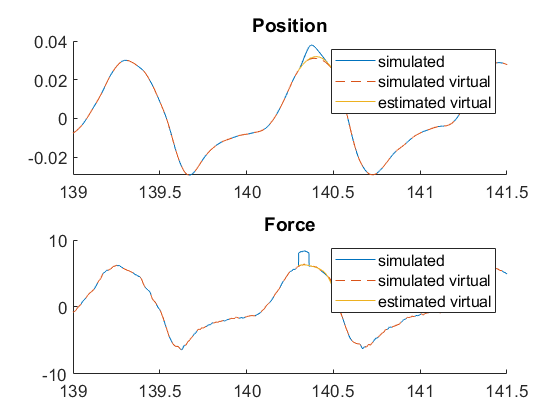

% real virtual trajectories
fz0 = out.virt_force.data;
z0 = out.virt_position.data;
%
figure('DefaultAxesFontSize',14)
subplot(2,1,1)
title('Position')
hold on
plot(t,z)
plot(t,z0, '--')
plot(delta_z.t_traject, delta_z.virt_traject, 'Color', [0.9290, 0.6940, 0.1250])
xlim([139 141.5])
legend('simulated', 'simulated virtual', 'estimated virtual')
subplot(2,1,2)
title('Force')
hold on
plot(t,fz)
plot(t,fz0, '--')
plot(delta_fz.t_traject, delta_fz.virt_traject, 'Color', [0.9290, 0.6940, 0.1250])
xlim([139 141.5])
legend('simulated', 'simulated virtual', 'estimated virtual')

% Actual simulated virtual trajectories 
delta_z_sim = copyObj(delta_z);
delta_fz_sim = copyObj(delta_fz);
delay_wdw = delta_z.delay;
estim_wdw = delta_z.estim_window;
for i = 1:delta_z_sim.nb_traject
    pert_interval = delta_z_sim.pert_ind(i)+(-2:estim_wdw+1)+delay_wdw;
    delta_z_sim.virt_traject(:,i) = z0(pert_interval);
    delta_fz_sim.virt_traject(:,i) = fz0(pert_interval);
end
delta_z_sim.computeDiffTraject('VirtTrajMethod', 'manual');
delta_fz_sim.computeDiffTraject('VirtTrajMethod', 'manual');

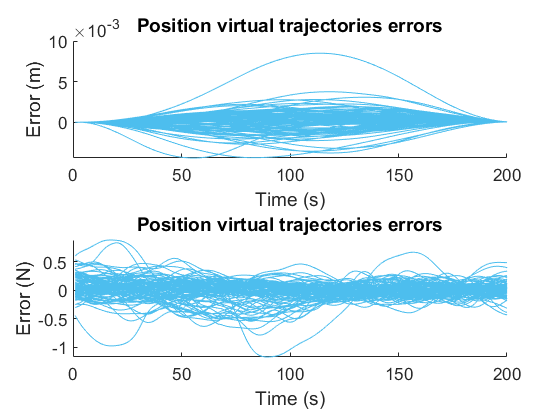

% 
figure('DefaultAxesFontSize',14)
subplot(2,1,1)
hold on
plot(delta_z.virt_traject-delta_z_sim.virt_traject, 'Color', [0.3010, 0.7450, 0.9330, 0.4])
title('Position virtual trajectories errors')
xlabel('Time (s)')
ylabel('Error (m)')
xlim([0, idx_wndw_imp_eval])
subplot(2,1,2)
hold on
plot(delta_fz.virt_traject-delta_fz_sim.virt_traject, 'Color', [0.3010, 0.7450, 0.9330, 0.4])
title('Position virtual trajectories errors')
xlabel('Time (s)')
ylabel('Error (N)')
xlim([0, idx_wndw_imp_eval])

### Discrete time identification algorithms

 We define two polynomials $A_k$ and $B_k \;$such as:


$$y\left(t\right)+a_1 y\left(t-1\right)+a_2 y\left(t-2\right)=b_2 \;u\left(t-2\right)+e\left(t\right)$$



$$A_k \left(q\right)y\left(t\right)=B_k \left(q\right)u\left(t\right)+e\left(t\right),$$


with $q$ the delay operator.

% Data formating for identification
for i = delta_z.nb_traject:-1:1 
    data{i} = iddata(delta_z.diff_traject(:,i), ...
        delta_fz.diff_traject(:,i),dt);
    data_sim{i} = iddata(delta_z_sim.diff_traject(:,i),...
        delta_fz_sim.diff_traject(:,i),dt); % ideal data
    data{i}.TimeUnit = 's';
    data{i}.InputUnit = 'N';
    data{i}.OutputUnit = 'm';
    data_sim{i}.TimeUnit = 's';
    data_sim{i}.InputUnit = 'N';
    data_sim{i}.OutputUnit = 'm'; 
end

The ARX identification method can now be used, since we know the order of the polynomials $A_k$ and $B_k$:

na = 2; % order of Ak
nb = 1; % order of Bk
nk = 2; % delay in Bk
for i = delta_z.nb_traject:-1:1 
    arx_id{i} = arx(data{i},[na nb nk],'IntegrateNoise',true);
    arx_id_sim{i} = arx(data_sim{i},[na nb nk]);
    arx_id{i}.Name = 'Arx ID';
    arx_id_sim{i}.Name = 'Arx ID with ideal data';
end

The quality of the identification can be estimated... to be continued...

%
for i = delta_z.nb_traject:-1:1 
    pem_id{i} = pem(data{i},arx_id{i});
    pem_id{i}.Name = 'Pem ID';
end

A random estimation is picked to compare the quality of the estimation:

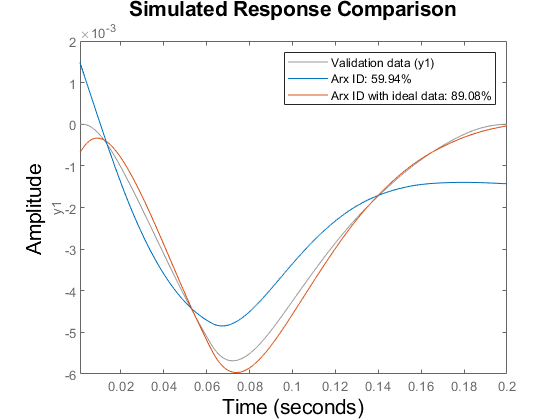

rand_idx = randi([1 delta_z.nb_traject],1,1);
figure('DefaultAxesFontSize',14)
compare(data{rand_idx},arx_id{rand_idx},arx_id_sim{rand_idx});

A wider overview is then displayed:

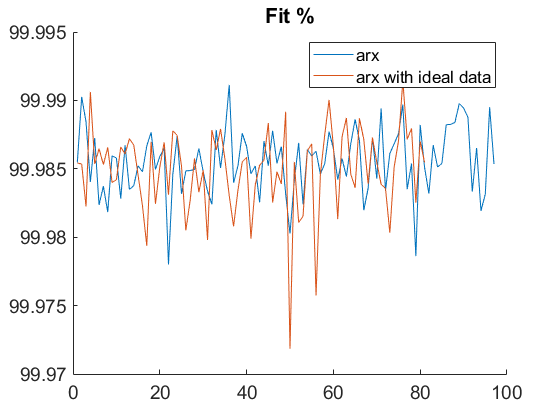

for i = delta_z.nb_traject:-1:1 
    arx_id_fit(i) = arx_id{i}.Report.Fit.FitPercent;
    arx_id_sim_fit(i) = arx_id{i}.Report.Fit.FitPercent;
end
figure('DefaultAxesFontSize',14)
hold on
plot(arx_id_fit)
plot(pem_id_fit)
title('Fit %')
legend('arx', 'arx with ideal data')

### Impedance parameters identification

Once the coefficients of $A_k$ and $B_k$ are identified, the impedance parameters can be deduced thanks to the relations detailed in the *Discretization* paragraph for every identification conducted for each perturbation:

% K D M identification
for i = 1:length(arx_id)
    % declare the equations system
    eq.A(1) = a1 - arx_id{i}.A(2) == 0;
    eq.A(2) = a2 - arx_id{i}.A(3) == 0;
    eq.B(2) = b2 - arx_id{i}.B(3) == 0;
    imp_param_id(i) = solve({eq.A(1),eq.A(2),eq.B(2)},[Ks;Bs;Ms]);
    if i == 1
        warning('off','all'); % to avoid  spam warnings in the loop
    end
end

warning('on','all')

## Results

text text

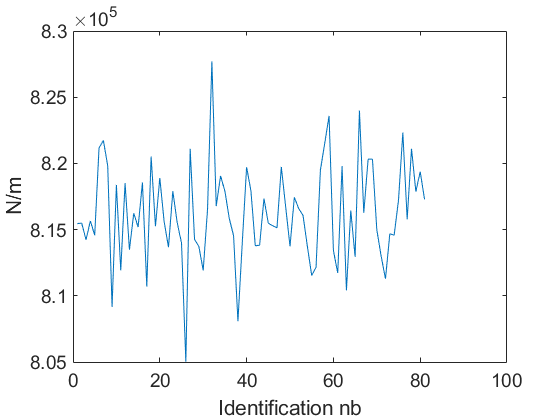

figure('DefaultAxesFontSize',14)
title('Stiffness')
plot([imp_param_id(:).Ks])
xlabel('Identification nb')
ylabel('N/m')

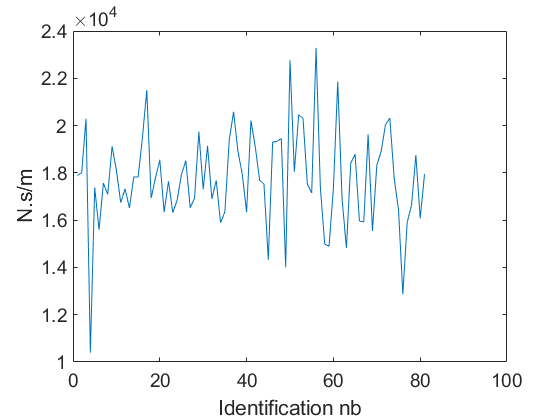

figure('DefaultAxesFontSize',14)
title('Damping')
plot([imp_param_id(:).Bs])
xlabel('Identification nb')
ylabel('N.s/m')

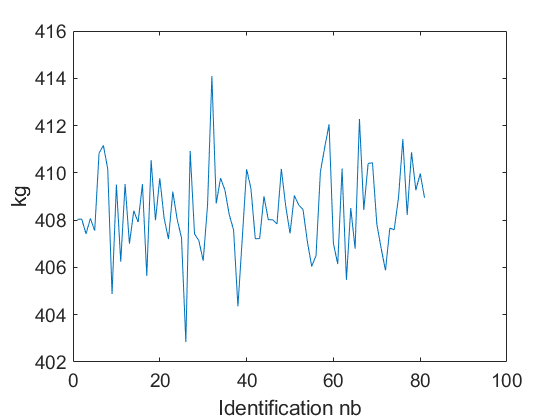

figure('DefaultAxesFontSize',14)
title('Mass')
plot([imp_param_id(:).Ms])
xlabel('Identification nb')
ylabel('kg')

## Annexes

### Functions

function F = root2d(X, eq)
syms Ks Bs Ms
F(1) = subs(eq.A(1), [Ks, Bs, Ms], [X(1), X(2), X(3)]);
F(2) = subs(eq.A(2), [Ks, Bs, Ms], [X(1), X(2), X(3)]);
F(3) = subs(eq.B(2), [Ks, Bs, Ms], [X(1), X(2), X(3)]);
end

function b = copyObj(a)
   b = eval(class(a));  %create default object of the same class as a
   for p =  properties(a).'  %copy all public properties
      try   %may fail if property is read-only
         b.(p{1}) = a.(p{1});
      catch
         warning('failed to copy property: %s', p);
      end
   end
end